Import the csv file ios_act.csv and remove unnecassery columns

ios_act_raw = readtable('ios_act.csv');
%Remove unnecassary columns 
ios_act = removevars(ios_act_raw, [1:4,12,13,17,21,25:47,49,50:54]);
head(ios_act,5) % show first 5 rows of table

ans = 5×17 table
    locationLatitude    locationLongitude    locationAltitude    locationSpeed    locationCourse    locationVerticalAccuracy    locationHorizontalAccuracy    accelerometerAccelerationX    accelerometerAccelerationY    accelerometerAccelerationZ    gyroRotationX    gyroRotationY    gyroRotationZ    magnetometerX    magnetometerY    magnetometerZ    activity
    ________________    _________________    ________________    _____________    ______________    ________________________    __________________________    __________________________    ___

Explore the data

activity = ios_act.activity;
automotive = ios_act.activity == 4;
%sum(automotive);
prop = ios_act.Properties;
sum(ismissing(ios_act)); %Check for missing values
%Count the number of the different activities
activitygrp = groupsummary(ios_act,"activity"); 

Preprosess the data

idx = isoutlier(ios_act,"median");
sum(idx);

Analyse the data visually

catlabels = ordinal(categorical(activitygrp.activity));
getlabels(catlabels);
catlabels = setlabels(catlabels,...
    {'Unknown','Stationary','Walking','Running','Automotive'})

catlabels = 5×1 ordinal array
     Unknown 
     Stationary 
     Walking 
     Running 
     Automotive 



barchart = bar(catlabels, activitygrp.GroupCount)

barchart =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [Unknown    Stationary    Walking    Running    Automotive]
        YData: [9914 20966 35104 9472 14464]

  Show all properties


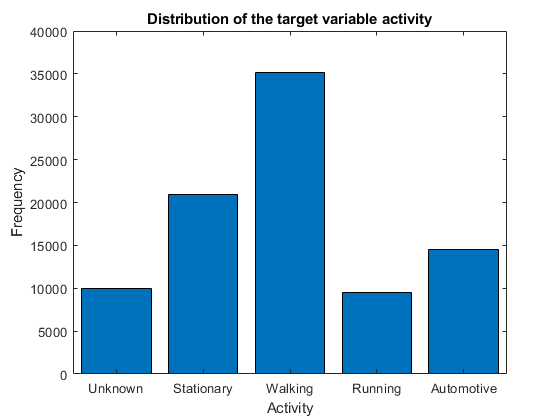

ax = ancestor(barchart, 'axes');
r = ax.YAxis;
r.TickLabelFormat = '%.g';
r.Exponent = 0;
title("Distribution of the target variable activity")
xlabel("Activity");
ylabel("Frequency");

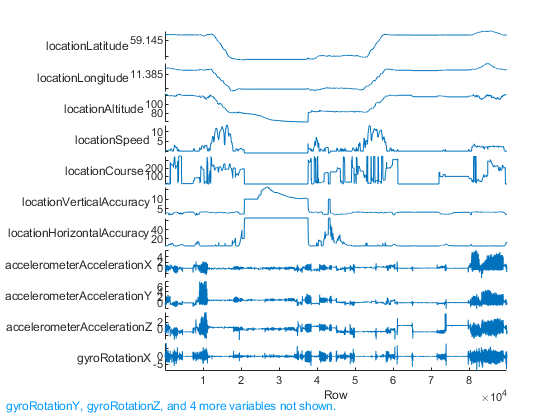


stackedplot(ios_act);


%densityplot(~value|variable,data = ios_act.mlt, scales = 
% list(x = list(relation = "free"), y = list(relation = "free"))
% ,adjust = 1.25, pch = "|", xlab = "Predictor")


Prepare the dataset for training and test

rng(8000,'twister'); %Set the random number generator to a known state

% Define a random (cross-validation) partition on a set of data of a specified size
iosactCVP = cvpartition(size(ios_act,1),'holdout',0.2) %holdout = test set

iosactCVP = Hold-out cross validation partition
   NumObservations: 89920
       NumTestSets: 1
         TrainSize: 71936
          TestSize: 17984

idx = iosactCVP.test;

%seperate to training and test data
dataTrain = ios_act(~idx,:);
dataTest = ios_act(idx,:);

Prepare the variables 

%Predictors and output variable in the training dataset
XTrain = dataTrain{:,1:16}; %Predictors
YTrain = dataTrain{:,17}; %Output variable

%Predictors and output variable in the test dataset
XTest = dataTest{:,1:16}; %Predictors
YTest = dataTest{:,17}; %Output variable

%Transforming the data from columns to rows
predictors = {transpose(table2array(dataTrain(:,1:16)))};
classescolumn = dataTrain{:,17};
targetclass = ({transpose(categorical(classescolumn))});


Prepare the hyper-parameters for the neural net


numFeatures = 16; %Number of predictors
%The number of hidden units corresponds to the amount of information
%remembered between time steps (the hidden state). The hidden state
%can contain information from all previous time steps, regardless 
%of the sequence length
numHiddenUnits = 200;
numClasses = 5; %Number of output classes

% The sequence input layer inputs sequence data to a network.
% The input size is set to the number of predictors

% The LTSM layer learns long-term dependencies between time
% steps in time series and sequence data. The number of hidden
% units corresponds to the amount of information remembered
% between time steps (the hidden state)
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',10, ...   %60 original
    'GradientThreshold',1, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'Verbose',0, ...
    'Plots','training-progress');

%'ValidationData',{XValidation,YValidation}, ...

Hyper-paramerts for optimisation

https://se.mathworks.com/help/deeplearning/ug/deep-learning-using-bayesian-optimization.html

%optimVars = [
%    optimizableVariable('MaxEpochs',[10 80],'Type','integer')
%    optimizableVariable('hiddenLayerSize',[50 300],'Type','integer')
%   ];

%function ObjFcn = makeObjFcn(XTrain,YTrain,XTest,YTest)
%ObjFcn = @valErrorFun;
%    function [valError,cons,fileName] = valErrorFun(optVars)

%ObjFcn = makeObjFcn(XTrain,YTrain,XTest,YTest);
%%optimizableVariable('MaxEpochs',[10 20 30 40 50 60 70 80],'Type','integer')

Start the training process

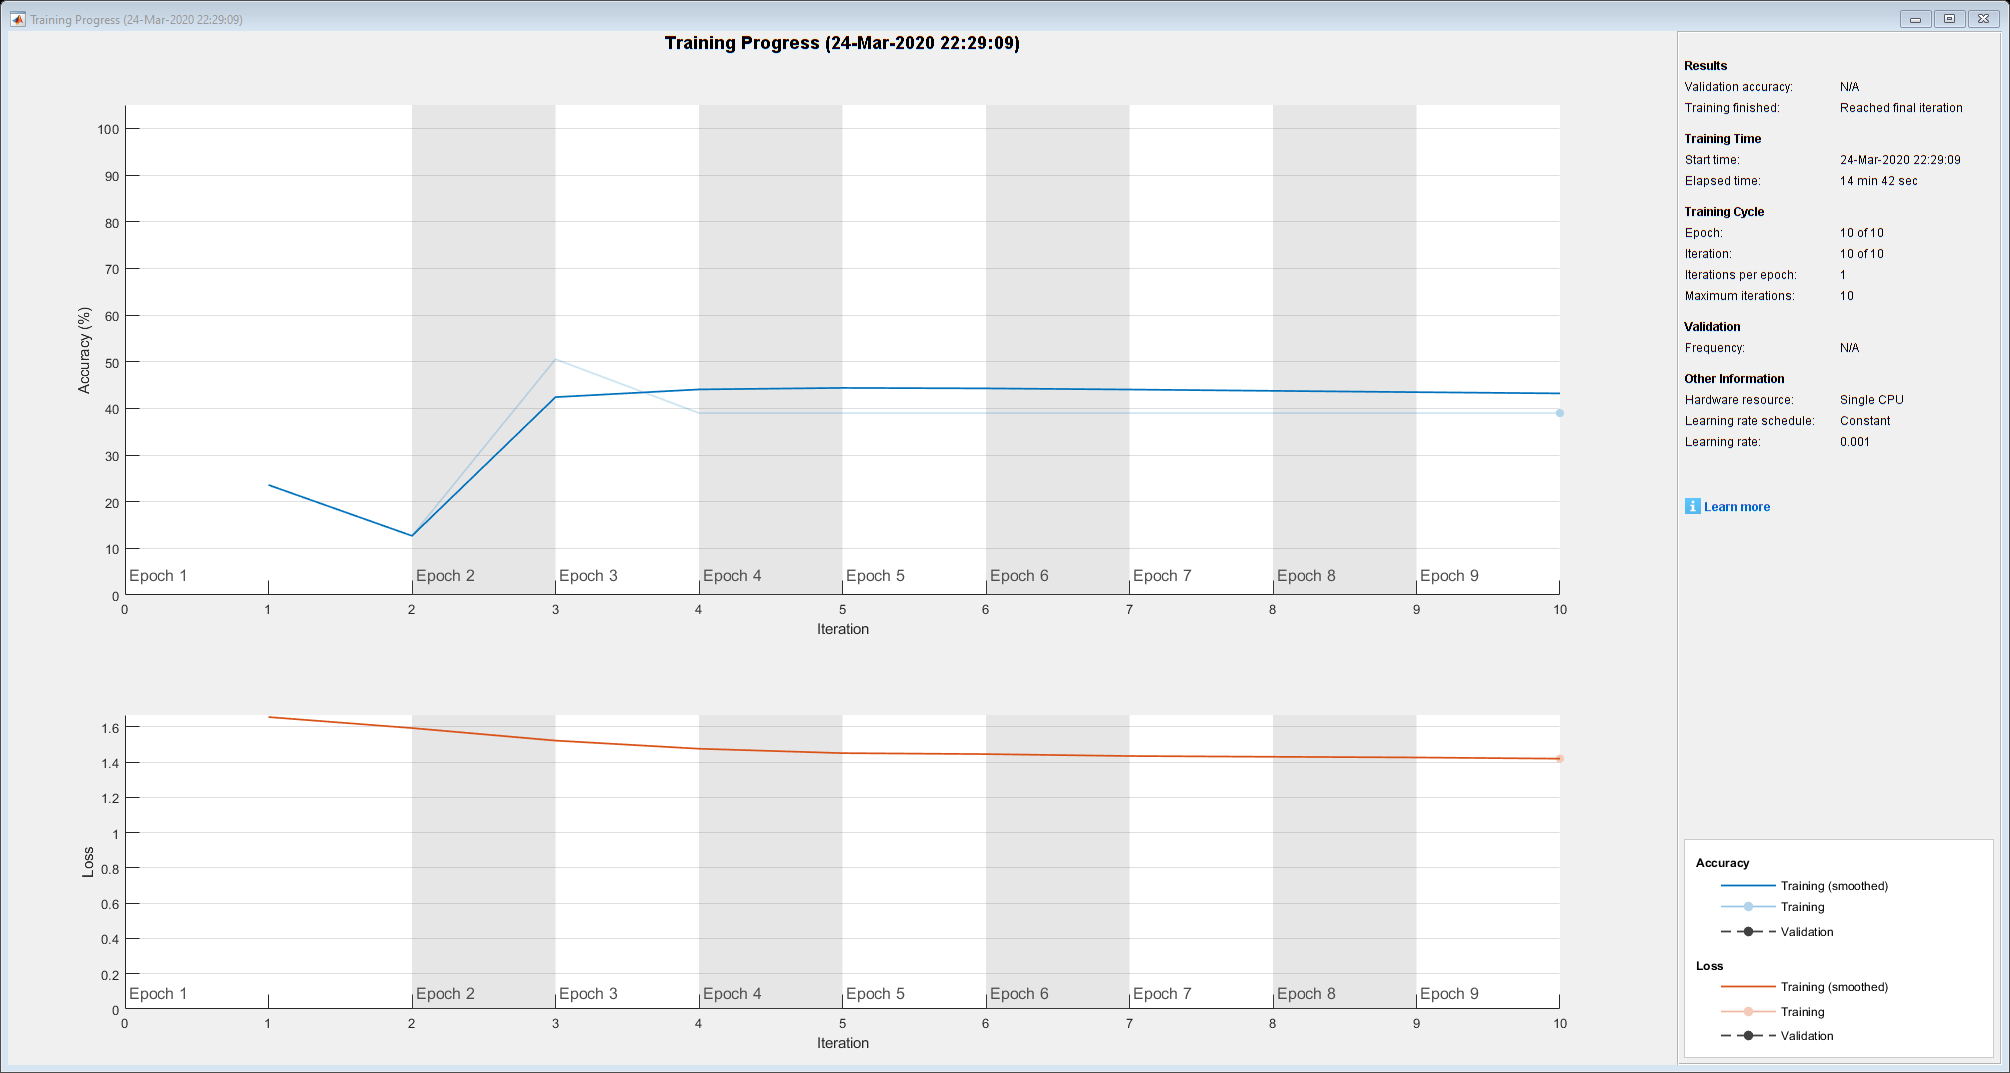

net = trainNetwork(predictors, targetclass, layers, options);

Analyse the network

analyzeNetwork(net)